**The Tabular value-fucntion methods on the cart and pole system**

Consider the cart-and-pole system here depicted:

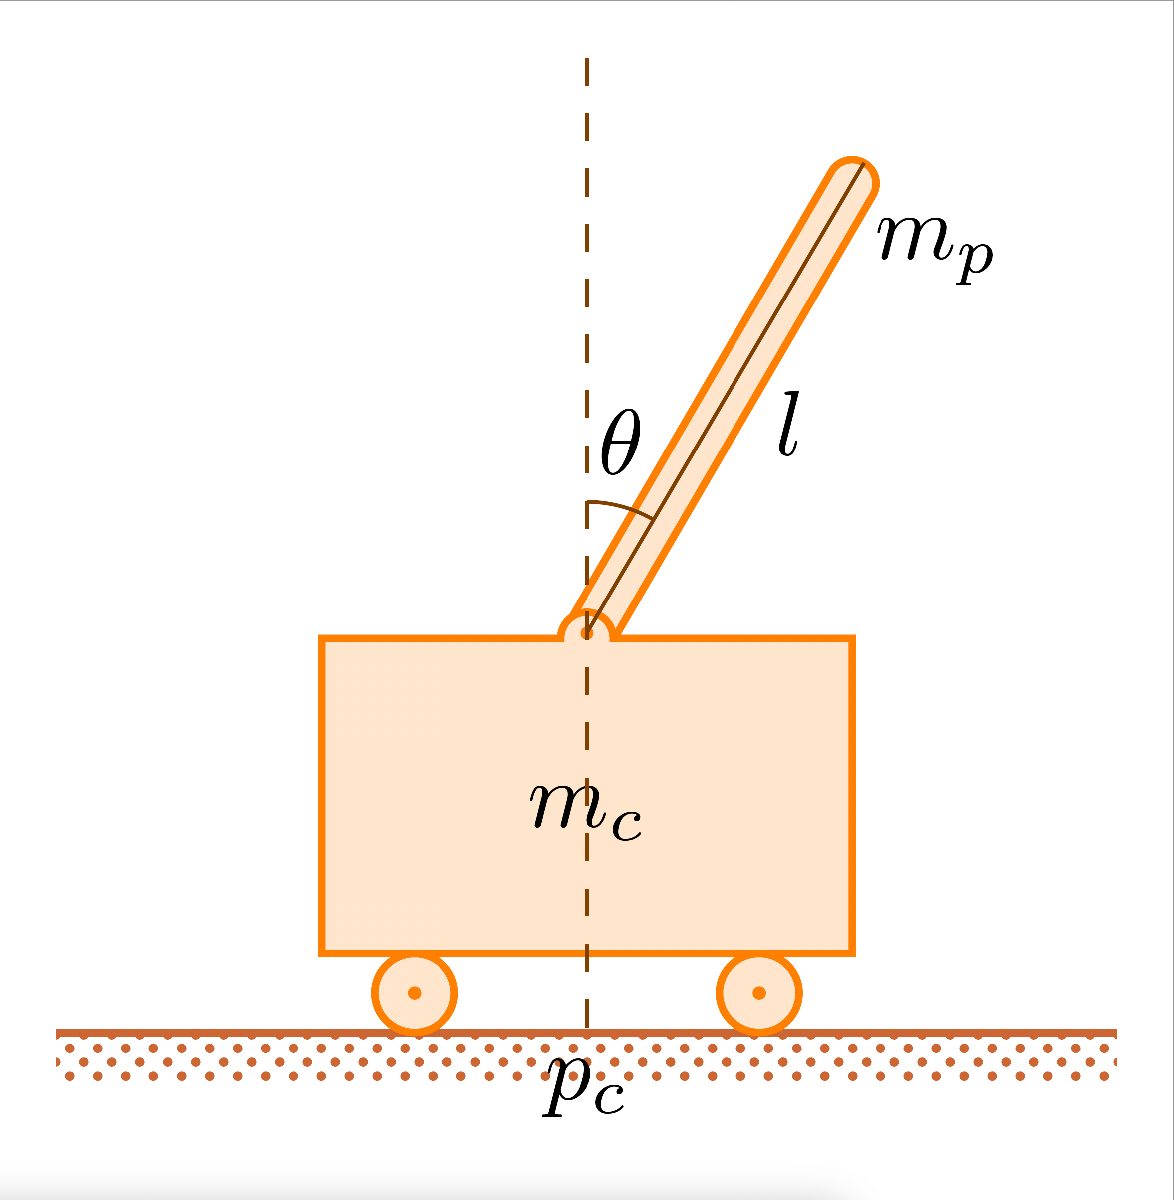

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

clear;
g=9.8;
m_c=1;
m_p=0.1;
l=0.5;
u_p=0.000002;
delta=0.02

delta = 0.0200

- Given the $$\mathcal{X}$$, $$\mathcal{U}$$ of the first hands-on define: the set of possible initial conditions of an episode; the terminal conditions of the episode

Answer: 

Let's recall the $X,U$of the first hands-on:


$$x = \left\{\begin{array}{rl}
x_1 = p_c \\
x_2 = \dot{p_c}\\
x_3 = \theta\\
x_4 = \dot{\theta}
\end{array}
\right.$$



$$u=F$$



$$x \in X \subseteq \mathbb{R}^4, u \in U \subseteq \mathbb{R} $$



$$X=\{x: x_1 \in \mathbb{R}, x_2 \in \mathbb{R}, x_3 \in \mathbb{R}, x_4 \in \mathbb{R}\}$$



$$U = \{-10,10 \}$$


The set of possible initial conditions is: $X_0=\{x: x_1 \in \mathbb{R}, x_2 \in \mathbb{R}, x_3 \in \left[-\frac{\pi}{ 10},\frac{\pi}{ 10}\right], x_4 \in \mathbb{R}\}$

The terminal conditions of the episode are:

- The state remains for 250 time-steps in the set $X_0$

-  The state leaves the set $X_0$

        2. Provide a proper discretization of the state space $$\mathcal{X}$$, and define the size of the action-value function $Q$

Answer:

Let's discretize the components of the state in this way:


$$x_1=\{]-\infty, -10[,[ -10, 10[, [10, +\infty[\}
$$



$$x_2=\{]-\infty, -5[,[ -5, 5[, [5, +\infty[\}
$$



$$x_3=\{]-\infty, -\pi[,[ -\pi, -\frac{\pi}{5}[, [-\frac{\pi}{5}, -\frac{\pi}{10}[,[-\frac{\pi}{10},\frac{\pi}{10}[,[\frac{\pi}{10},\frac{\pi}{5}[,[\frac{\pi}{5},\pi[,[\pi +\infty[\}
$$



$$x_4=\{]-\infty, -2[,[ -2, 2[, [2, +\infty[\}
$$


Now let's code it:

global d xi;    
x1=[-inf -1 -0.3 0.3 1 inf];
x2=[-inf -0.5 -0.2 0.2 0.5 inf];
x3=[-inf deg2rad(-10) deg2rad(-5) deg2rad(5) deg2rad(10) inf];
x4=[-inf -0.5 -0.2 0.2 0.5 inf];
d=[size(x1,2) size(x2,2) size(x3,2) size(x4,2)];
xi=[x1 x2 x3 x4];

        3. Create a code able to select the discretized version of a measured state $x$

Answer: 

       4. Given the terminal conditions of the episode (selected in 1.) create a code able to perform a fixed number of episodes of a fixed number of steps, starting from random initial conditions and applying random inputs.

T=5/delta;
%initialize the time interval
tspans = 0;
numEpisodes=1000;
for j=1:T
    tspans=[tspans tspans(end)+delta];
end
% 
% for k=1:numEpisodes
%     x0=rand(1,4);
%     x0(3)=-0.0175 + 0.035 * rand();
%     nTime = length(tspans)-1; %sets the number of iterations
%     xs_list = zeros(nTime, length(x0)); %initialize the list of values of the state movement
%     xs_list(1, :) = x0; %sets the initial condition as the first value 
%     t2=0;
%     %simulate the dynamics of the system
%     for i = 1:nTime
%           if ((x0(3)<x3(2)) || (x0(3)>x3(7)))
%               break;
%           end
%       t1=t2;
%       t2=tspans(i+1);
%       if rand() < 0.5
%         u = 10;
%       else
%         u = -10;
%       end
%       [t_, x_] = ode45(@(t,x)odefc(x, g, m_c, m_p, u_p, l, u), [t1,t2], x0); %simulates between 2 consecutive values of the time interval
%       tp = find(t_ == t2);
%       x0       = x_(tp, :); %x^(k)=x^(k+1)
%       xs_list(i+1, :) = x0; %adds the value obtained to the list
%     end
% end
% subplot(2,2,1)
% plot(1:size(xs_list,1),xs_list(:,1),'-')
% title('Position')
% xlabel('k')
% ylabel('x_1(k)')
% subplot(2,2,2)
% plot(1:size(xs_list,1),xs_list(:,2),'-')
% title('Velocity')
% xlabel('k')
% ylabel('x_2(k)')
% subplot(2,2,3)
% plot(1:size(xs_list,1),xs_list(:,3),'-')
% title('Theta')
% xlabel('k')
% ylabel('x_3(k)')
% subplot(2,2,4)
% plot(1:size(xs_list,1),xs_list(:,4),'-')
% title('Angular velocity')
% xlabel('k')
% ylabel('x_4(k)')

      5. Create a function able to perform $$\epsilon$$-greedy policy for a chosen $$\epsilon$$.

He have the function egpolicy, which takes as parameters the state $x$, the 5-D matrix Q and the number of the current episode and returns the chosen control input and its index in the table:

% Q=zeros(d(1)-1, d(2)-1, d(3)-1, d(4)-1, 2); %example
% k=3; %example
%x=[0.3 0.1 deg2rad(10) 0.4]; %example
% [uindex,u]=egpolicy(x,Q,k)
%disc(x)

      6. Create a code that applies Tabular Q-Learning algorithm.

Q=zeros(d(1)-1, d(2)-1, d(3)-1, d(4)-1, 2); %initialize the Q
alpha=0.01; %initialize the learning rate
gamma=0.95; %initialize the discount factor
r=zeros(1,numEpisodes); %reward vector-stores the cumulative discounted rewards of each episode
U=[];
for e=1:numEpisodes %iterate for each episode
    x0=-0.0175 + 0.035 * rand(1,4); %set a random initial condition
    %x0=zeros(1,4);                      
    nTime = length(tspans)-1; %sets the number of iterations
    xs_list = zeros(nTime, length(x0)); %initialize the list of values of the state movement
    xs_list(1, :) = x0; %sets the initial condition as the first value 
    t2=0;
    %simulate the dynamics of the system
    for i = 1:nTime
      if (x0(3)<=deg2rad(-10)) || (x0(3)>=deg2rad(10)) || ((x0(1)<=-1) || (x0(1)>=1)) %if the state leaves the set X0
          break; %terminate the episode
      end
      t1=t2;
      t2=tspans(i+1);
      [iu,u]=egpolicy(x0,Q,e); %perform the epsilon-greedy policy
      if e==numEpisodes
          U=[U u];
      end
      [t_, x_] = ode45(@(t,x)odefc(t, x, g, m_c, m_p, u_p, l, u), [t1,t2], x0); %simulates between 2 consecutive time steps
      tp = find(t_ == t2);
      discX0=disc(x0); %discretize x^(k)
      discX1=disc(x_(tp, :)); %discretize x^(k+1)
      r(e)=r(e)+(gamma^(i-1))*reward(x_(tp, :)); %compute the cumulative discounted reward of the episode
      Q(discX0(1),discX0(2),discX0(3),discX0(4),iu)=Q(discX0(1),discX0(2),discX0(3),discX0(4),iu)+alpha*(reward(x_(tp,:))+gamma*max(Q(discX1(1),discX1(2),discX1(3),discX1(4),:))-Q(discX0(1),discX0(2),discX0(3),discX0(4),iu)); %compute the new Q(x^(k),u^(k))
      Q(discX0(1),discX0(2),discX0(3),discX0(4),iu)=Q(discX0(1),discX0(2),discX0(3),discX0(4),iu)+alpha*(reward(x_(tp,:))+gamma*Q(discX1(1),discX1(2),discX1(3),discX1(4),iu1)-Q(discX0(1),discX0(2),discX0(3),discX0(4),iu)); %compute the new Q(x^(k),u^(k))

      x0       = x_(tp, :); %x^(k)=x^(k+1)
      xs_list(i+1, :) = x0; %adds the value obtained to the list
    end
end

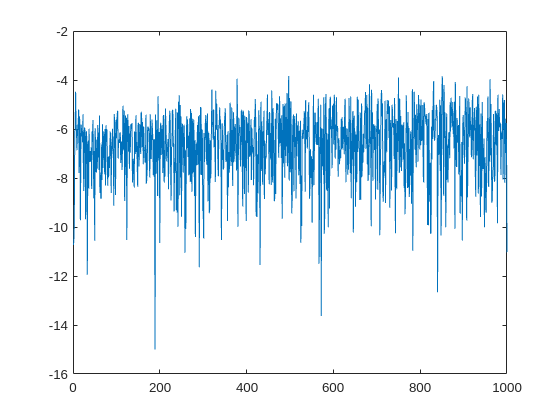

figure();
plot(r) %plot the cumulative discounted rewards

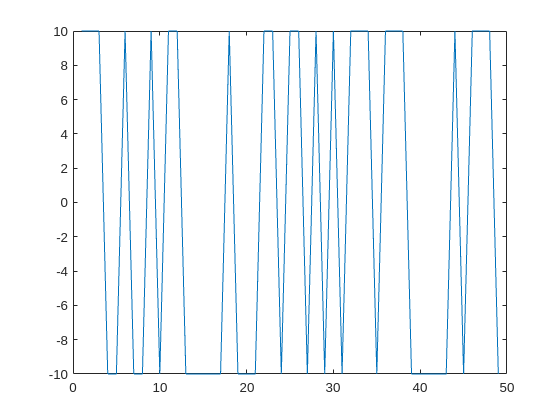

figure();
plot(U);

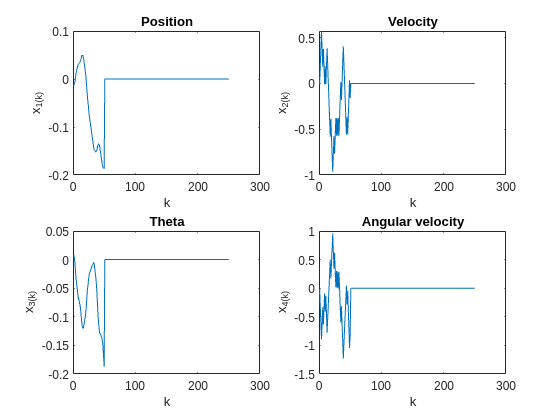


figure();
%plots the last episode 
subplot(2,2,1)
plot(1:size(xs_list,1),xs_list(:,1),'-')
title('Position')
xlabel('k')
ylabel('x_1(k)')
subplot(2,2,2)
plot(1:size(xs_list,1),xs_list(:,2),'-')
title('Velocity')
xlabel('k')
ylabel('x_2(k)')
subplot(2,2,3)
plot(1:size(xs_list,1),xs_list(:,3),'-')
title('Theta')
xlabel('k')
ylabel('x_3(k)')
subplot(2,2,4)
plot(1:size(xs_list,1),xs_list(:,4),'-')
title('Angular velocity')
xlabel('k')
ylabel('x_4(k)')

      7. Copy and paste your Q-learning algorithm and apply the changes needed to convert it into a SARSA algorithm

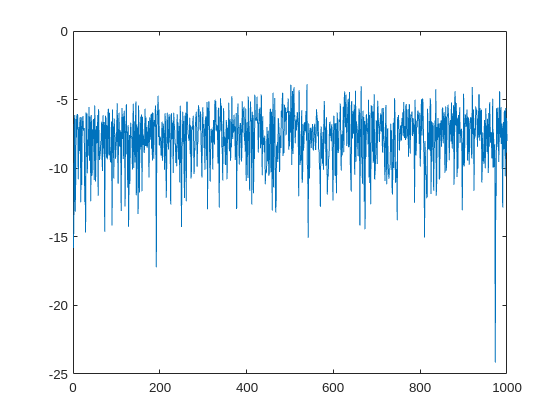

Q=zeros(d(1)-1, d(2)-1, d(3)-1, d(4)-1, 2); %initialize the Q
alpha=0.01; %initialize the learning rate
gamma=0.95; %initialize the discount factor
r=zeros(1,1000); %reward vector-stores the cumulative discounted rewards of each episode
for e=1:numEpisodes %iterate for each episode
    x0=-0.0175 + 0.035 * rand(1,4); %set a random initial condition
    nTime = length(tspans)-1; %sets the number of iterations
    xs_list = zeros(nTime, length(x0)); %initialize the list of values of the state movement
    xs_list(1, :) = x0; %sets the initial condition as the first value 
    t2=0;
    [iu,u]=egpolicy(x0,Q,e); %perform the epsilon-greedy policy
    %simulate the dynamics of the system
    for i = 1:nTime
      if (x0(3)<deg2rad(-20)) || (x0(3)>deg2rad(20)) || ((x0(1)<-5) || (x0(1)>5)) || (x0(2)<-5) || (x0(2)>5) || ((x0(4)<-5)) || (x0(4)>5) %if the state leaves the set X0
          break; %terminate the episode
      end
      t1=t2;
      t2=tspans(i+1);
      [t_, x_] = ode45(@(t,x)odefc(t, x, g, m_c, m_p, u_p, l, u), [t1,t2],x0); %simulates between 2 consecutive time-steps
      tp = find(t_ == t2);
      [iu1,u1]=egpolicy(x_(tp, :),Q,e); %perform the epsilon-greedy policy
      discX0=disc(x0); %discretize x^(k)
      discX1=disc(x_(tp, :)); %discretize x^(k+1)
      r(e)=r(e)+(gamma^i)*reward(x_(tp, :)); %compute the cumulative discounted reward of the episode
      Q(discX0(1),discX0(2),discX0(3),discX0(4),iu)=Q(discX0(1),discX0(2),discX0(3),discX0(4),iu)+alpha*(reward(x_(tp,:))+gamma*Q(discX1(1),discX1(2),discX1(3),discX1(4),iu1)-Q(discX0(1),discX0(2),discX0(3),discX0(4),iu)); %compute the new Q(x^(k),u^(k))
      x0       = x_(tp, :); %x^(k)=x^(k+1)
      xs_list(i+1, :) = x0; %adds the value obtained to the list
      u=u1; %u^(k)=u^(k+1)
      iu=iu1; %update of the index of the control input
    end
end
figure();
plot(r) %plot the cumulative discounted rewards

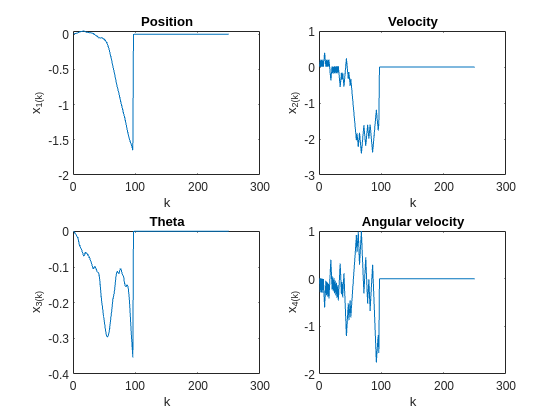


%plots the last episode
figure();
%plots the last episode 
subplot(2,2,1)
plot(1:size(xs_list,1),xs_list(:,1),'-')
title('Position')
xlabel('k')
ylabel('x_1(k)')
subplot(2,2,2)
plot(1:size(xs_list,1),xs_list(:,2),'-')
title('Velocity')
xlabel('k')
ylabel('x_2(k)')
subplot(2,2,3)
plot(1:size(xs_list,1),xs_list(:,3),'-')
title('Theta')
xlabel('k')
ylabel('x_3(k)')
subplot(2,2,4)
plot(1:size(xs_list,1),xs_list(:,4),'-')
title('Angular velocity')
xlabel('k')
ylabel('x_4(k)')

function dxdt = odefc(t, x, g, m_c, m_p, u_p, l, f) %defines the differencial equation
        dpdt = zeros(2, 1);
	    dthetadt = zeros(2, 1);
        dthetadt(1) = x(4);
	    dthetadt(2) = (g*sin(x(3))+cos(x(3))*((-f-m_p*l*(x(4)^2)*sin(x(3)))/(m_c+m_p))-(u_p*x(4))/(m_p*l))/(l*((4/3-(m_p*(cos(x(3)))^2)/(m_c+m_p))));
	    dpdt(1) = x(2);
	    dpdt(2) = (f+m_p*l*(((x(4))^2)*sin(x(3))-dthetadt(2)*cos(x(3))))/(m_c+m_p);
        dxdt = [dpdt; dthetadt];
end

function discX = disc(x)
    global d xi;
    discX=zeros(1,4);
    k=0;
    for i=1:4
        for di=1:d(i)-1
            if (x(i) >=  xi(di+k)) && (x(i) < xi(di+k+1)) 
                discX(i)= di;
                break;
            end
        end
        k=k+d(i);
    end
end

function [iu,u]=egpolicy(x,Q,k)
    epsilon=1/k;
    if rand() <= epsilon
        if rand() < 0.5
            iu=1;
            u = -10;
        else
            iu=2;
            u = 10;
        end
    else
        discX=disc(x);
        Q0=Q(discX(1),discX(2),discX(3),discX(4),:);
        indexU=find(Q0==max(Q0));
        if numel(indexU)==2
            if rand() < 0.5
                iu=1;
                u = -10;
            else
                iu=2;
                u = 10;
            end
        else
            if indexU==1
                iu=1;
                u=-10;
            else
                iu=2;
                u=10;
            end
        end    
    end
end

function r=reward(xk1)
    % r=0;
    % if (xk1(3)<=deg2rad(-10)) || (xk1(3)>=deg2rad(10)) || ((xk1(1)<=-1) || (xk1(1)>=1))
    %     r=-100;
    % end
    r=-norm(xk1);
end